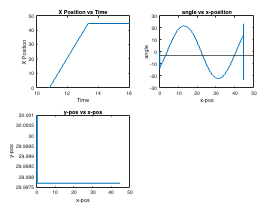

plot_1 = false;
plot_2 = false;
plot_3 = true;
if plot_1 == true  
    % Define the file name
    file_name = 'position_85_tooslow.csv';
    
    % Read the CSV file
    data = csvread(file_name, 6250); % Skip the first 6000 rows
    
    % Extract time (1st column) and x position (4th column)
    time = data(:, 1);
    x_position = data(:, 4);

    % Plot
    figure
    plot(time, x_position);
    xlabel('Time');
    ylabel('X Position');
    title('X Position vs Time');

    % Extract time (1st column) and x velocity (5th column)
    x_velocity = data(:, 5);
    
    % Plot
    figure
    plot(time, x_velocity);
    xlabel('Time');
    ylabel('X Velocity');
    title('X Velocity vs Time');
end

if plot_2 == true  
    % Define the file name
    file_name = 'velocity_to_85_blocking.csv';
    
    % Read the CSV file
    data = csvread(file_name, 6250); % Skip the first 6000 rows
    
    % Extract time (1st column) and x position (4th column)
    time = data(:, 1);
    x_position = data(:, 4);

    % Plot
    figure
    plot(time, x_position);
    xlabel('Time');
    ylabel('X Position');
    title('X Position vs Time');

    % Extract time (1st column) and x velocity (5th column)
    x_velocity = data(:, 5);
    
    % Plot
    figure
    plot(time, x_velocity);
    xlabel('Time');
    ylabel('X Velocity');
    title('X Velocity vs Time');
end


if plot_3 == true  
    % Define the file name
    file_name = 'test_with_angle.csv';
    
    % Read the CSV file
    data = csvread(file_name, 10000); % Skip the first 6000 rows
    
    % Extract time (1st column) and x position (4th column)
    time =  data(:,1);
    x_position = data(:, 4);
    angle = data(:, 15);
    y_position = data(:,6);
    
    figure;
    subplot(2,2,1);
    plot(time, x_position);
    xlabel('Time');
    ylabel('X Position');
    title('X Position vs Time');
    subplot(2,2,2);
    plot(x_position, angle);
    xlabel('x-pos');
    ylabel('angle');
    title('angle vs x-position');
    yline(mean(angle));
    subplot(2,2,3);
    plot(x_position, y_position);
    xlabel('x-pos');
    ylabel('y-pos');
    title('y-pos vs x-pos');

    
end